# Electrode Charge

Select custom dump file

clear variables;

fileName = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\grouped\tip4p_cs_2V_ar_long\dump.allq.CsCat_2V_1elec.xyz";

[time,col_names,numAtoms,xbounds,ybounds,zbounds] = scan_DumpCustom(fileName);

if ~contains(col_names,'q')
    error("Missing charge data in Dumpfile");
elseif ~contains(col_names,'x') %asumes x,y,z all come together. 
    error("Missing position data in Dumpfile");
end

% zbounds{1}(2) = 8;

Time Units set in LAMMPS

time_units = 1000;

Timestep of Simulation

timestep = 1/time_units;
maxTime = max(time)/time_units;

Plot Time (in ps)

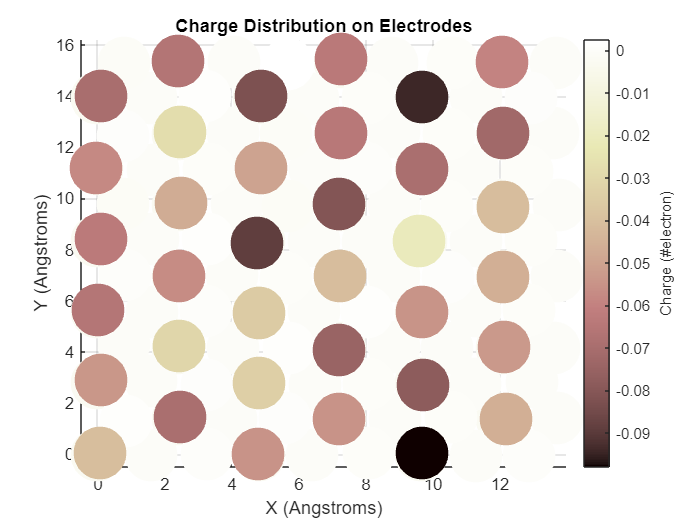

plotTime = 905;

[plotTable,timeTrue] = parse_DumpCustomOne(fileName, plotTime*time_units);
plotTable = plotTable(plotTable.id <= 144,:);

timeps = timeTrue*timestep;
figure;
colormap pink;
scatter3(plotTable,'x','y','z','filled','ColorVariable','q','SizeData',1000);
xlabel('X (Angstroms)');
ylabel('Y (Angstroms)');
zlabel('Z (Angstroms)');
title('Charge Distribution on Electrodes');
cb = colorbar;                                     % create and label the colorbar
cb.Label.String = 'Charge (#electron)';
axis([xbounds{1} ybounds{1}]);
view(0,90);

Total Charge - Lower Electrode

totalCharge = sum(plotTable(plotTable.z < zbounds{1}(2)/2,:).q);
disp(totalCharge);

   -2.1519



Total Charge - Higher Electrode

totalCharge = sum(plotTable(plotTable.z > zbounds{1}(2)/2,:).q);
disp(totalCharge);

     0

